# ASSIGNMENT 4

Gianpaolo Mastroiacovo(ge28tud)

Antonio Di Giovanni(03743324)

Date(18/05/2021)

## Exercise 4.1)

#### *a)*

Constraint (2) enforces the departures from every location, except for the depot $\left(\forall \;\;i:1\le i\le N\right)$, to be exactly one, as the sum of each row over all of the column has to be equal to 1. Constraint (1), instead, enforces the number of departures from a whatever location to be equal to the number of arrivals in that same location, i. e. one for every customer, as per constraint (2), but any value $1\le z\le N$for the depot.

#### *b)*

Constraint $\left(4\right)$ ensures that the quantity delivered to each customer is positive and not larger than the maximum capacity of the vehicle $\bar{V}$: If for a given customer $x_{i,j} =0$, the right-hand side constraint $\left(5\right)$takes value 0, forcing $q_{i,j}$ to be $\le 0$. At the same time, $\left(4\right)$ forces this quantity to be non negative $\left(q_{i,j} \ge 0\right)$,  that makes it exactly $0$. Similarly, if $x_{i,j} =1$, according to $\left(5\right)$, $q_{i,j}$ could take any value between 0 and $M$(which is larger than the optimal $\bar{V}$), in this case$\left(4\right)$ makes sure the maximum value assumed by $q_{i,j}$ is $\bar{V}$.

#### *c)*

In constrains $\left(3\right)$, the difference between the quantity in the vehicle when reaching a certain customer $i$ from location $k$and the quantity in the vehicle when leaving the customer $i$ towards a certain location$j$ is set to be equal to the demand of customer $i$. This implies that the packages delivered to that customer in that trip are exactly the demand of $i$, i. e. the demand of customer $i$ is satisfied all at once.

NEGATIVE?

#### *d)*

*Constraint *$\left(3\right)$ forces $q_{i,j}$ to be equal to the $q$ of the previously served customer minus the demand of the previous customer. When all of the demands of the customers that still have to be served are larger than the "remaining" $q_{i,j}$, and since $q_{i,j}$ cannot assume negative values because of $\left(8\right)$, the only possible choice is to go back to the deposit ($\left(3\right)$is only applied $\forall \;\;i:1\le i\le N$, i.e. not for the deposit). 

*Questions:*

- ***In Exercise 4.3 c) s*****hould we do the fewest number of extra-trips possible or one per customer?**

## Exercise 4.2)

load data_4.2.mat

x4_2b = zeros(N+1,N+1,10);

Capacity4_2b = [];
m=0;
for l=0:0.5:4.5
vehicle_cost = l;    
m=m+1;
Capacity = intvar(1);
M=100;
N=length(customer_demands)
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];


obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all"));

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
ops = sdpsettings ('solver','gurobi', 'gurobi.MIPGap',0.2);


Result = optimize(Cons, obj, ops);

    Capacity4_2b = [Capacity4_2b, value(Capacity)];
    x4_2b(:,:,m) = value(x);

%q4_1a = value(q)
%x4_1a = value(x) 
%Obj4_1a = value(obj) 
    if l==0
        Capacity4_2a = value(Capacity);
    end
end

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x357b53b0
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 9.9777114
Presolve removed 528 rows and 33 columns
Presolve time: 0.01s
Presolved: 286 rows, 480 columns, 1410 nonzeros
Variable types: 240 continuous, 240 integer (240 binary)

Root relaxation: objective 2.951222e+00, 351 iterations, 0.00 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    2.95122    0   26    9.97771    2.95122 

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0xb97bf084
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 22.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 1.126482e+01, 449 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   11.26482    0   59   22.97771   11.26482

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x2c93e458
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 35.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 1.828165e+01, 344 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   18.28165    0   52   35.97771   18.28165

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x479b940f
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 2e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 48.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 2.526980e+01, 364 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   25.26980    0   68   48.97771   25.26980

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0xe8796407
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 2e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 61.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 3.225379e+01, 349 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   32.25379    0   68   61.97771   32.25379

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x77412a16
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 3e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 74.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 3.923779e+01, 376 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   43.37469    0   52   74.97771   43.37469

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0xab7ef699
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 3e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 87.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 4.622178e+01, 376 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   51.37469    0   52   87.97771   51.37469

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x561e3e33
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 4e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 100.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.320577e+01, 456 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   59.37469    0   52  100.97771   59.3746

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x75b4f4e7
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 4e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 113.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.018976e+01, 456 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   67.37469    0   52  113.97771   67.3746

N = 15

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 814 rows, 513 columns and 2450 nonzeros
Model fingerprint: 0x3f40be7d
Variable types: 256 continuous, 257 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 5e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 126.9777114
Presolve removed 288 rows and 32 columns
Presolve time: 0.03s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.717376e+01, 456 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   75.37469    0   52  126.97771   75.3746

#### *b)*

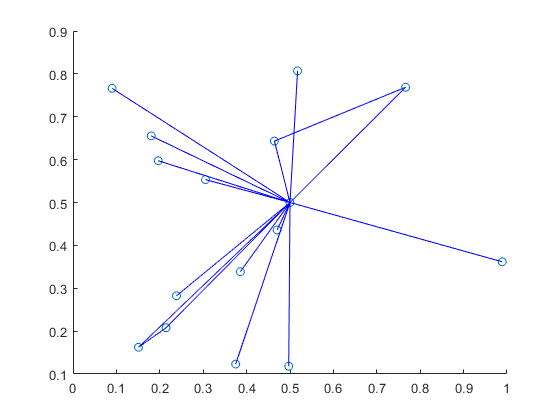

%colors = randi(0:1,1,N+1)
scatter(locations(:,1),locations(:,2));
hold on 
for i=1:N+1
    for j=1:N+1
        if(value(x(i,j))==1)    
            plot(locations([i,j],1),locations([i,j],2),"Color",'b');
        end
    end
end
hold off

When $c^V$ is changed from its nominal value, the 

Capacity4_2b

Capacity4_2b =     98    19    16    16    16    16    19    16    16    16


x4_2b

x4_2b = x4_2b(:,:,1) =

     1     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     1

The routes instead ...

Rifare il grafico in modo da averne 3 in un for loop, o fare uno a valori di vehicle_cost bassi,medi.alti.

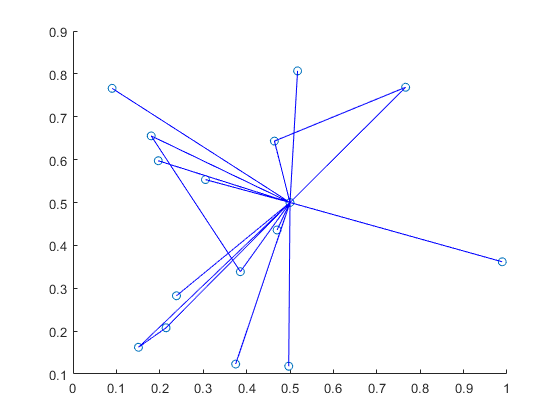

for l=1:size(x4_2b,3)
    scatter(locations(:,1),locations(:,2));
hold on 
for i=1:N+1
    for j=1:N+1
        if(value(x4_2b(i,j,l))==1)    
            plot(locations([i,j],1),locations([i,j],2),"Color",'b');
        end
    end
end
hold off
end

#### *c)*

We will look for the solution with a maximum gap of 20% from the optimal one, as the solver takes several minutes to run on our computers.

load data_4.2.mat

cTau = [];
nTravels = [];
objective = [];
Capacities = [];
for l=0:0.05:1
Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full');
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];



c_tau = l;

obj = vehicle_cost * Capacity +  (travel_cost * sum(distances .* x,"all") + c_tau*T)

%ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);


Result = optimize(Cons, obj, ops);

cTau = [cTau, c_tau];
nTravels = [nTravels, T];
objective = [objective, value(obj)];
Capacities = [Capacities, Capacity];
end

Linear scalar (real, integer, 241 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x2c722911
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 11.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 4.883948e+00, 333 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    4.88395    0   53   11.57783    4.88395

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.05 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xf030fb04
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [5e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 12.3278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 4.963622e+00, 291 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    4.96362    0   53   12.32783    4.96362

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x2d7e244f
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 13.0778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.043296e+00, 363 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.04330    0   53   13.07783    5.04330

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xea6c3bc9
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 13.8278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.122970e+00, 329 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.12297    0   53   13.82783    5.12297

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x0787fc44
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 14.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.202644e+00, 362 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.20264    0   53   14.57783    5.20264

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x9c1b355b
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 15.3278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.282318e+00, 367 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.28232    0   53   15.32783    5.28232

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x434024a6
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 16.0778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.01s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.361992e+00, 486 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.36199    0   53   16.07783    5.36199

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x3abb2532
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 16.8278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.441666e+00, 331 iterations, 0.00 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.44167    0   53   16.82783    5.44167

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xc59139cd
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 17.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.521340e+00, 342 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.52134    0   53   17.57783    5.52134

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xff1f9523
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 18.3278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.601014e+00, 338 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.60101    0   53   18.32783    5.60101

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x41fa2da8
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 19.0778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.680688e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.68069    0   53   19.07783    5.68069

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x23941f56
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 19.8278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.760362e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.76036    0   53   19.82783    5.76036

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x21382c2a
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 20.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.840036e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.84004    0   53   20.57783    5.84004

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x47150294
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 21.3278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.01s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.919710e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.91971    0   53   21.32783    5.91971

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x84abf850
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 22.0778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 5.999384e+00, 519 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    5.99938    0   53   22.07783    5.99938

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xc134e62a
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 22.8278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.079058e+00, 519 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.07906    0   53   22.82783    6.07906

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xf268b95d
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 23.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.01s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.158732e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.15873    0   53   23.57783    6.15873

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x0e0a90eb
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 24.3278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.238406e+00, 519 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.23841    0   53   24.32783    6.23841

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0x37db40b5
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 25.0778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.318080e+00, 507 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.31808    0   53   25.07783    6.31808

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 0.98583


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xf1c2442c
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 25.8278304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.397754e+00, 519 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.39775    0   53   25.82783    6.39775

Linear scalar (real, integer, 242 variables)
Coefficients range: 0.060229 to 1


Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 815 rows, 514 columns and 2467 nonzeros
Model fingerprint: 0xe0a12e7b
Variable types: 256 continuous, 258 integer (256 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [6e-02, 1e+00]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+01]
Found heuristic solution: objective 26.5778304
Presolve removed 289 rows and 33 columns
Presolve time: 0.02s
Presolved: 526 rows, 481 columns, 3780 nonzeros
Variable types: 240 continuous, 241 integer (240 binary)

Root relaxation: objective 6.477428e+00, 519 iterations, 0.01 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    6.47743    0   53   26.57783    6.47743

A =  [];
A(:,1) = value(cTau)';
A(:,2) = value(nTravels)';
A(:,3) = value(Capacities)';
A(:,4) = value(objective)';
A

A =          0    8.0000   28.0000    8.4450
    0.0500    7.0000   28.0000    8.7881
    0.1000    5.0000   36.0000    9.0935
    0.1500    5.0000   36.0000    9.3435
    0.2000    5.0000   36.0000    9.5935
    0.2500    5.0000   36.0000    9.8435
    0.3000    5.0000   36.0000   10.0935
    0.3500    5.0000   36.0000   10.3435
    0.4000    4.0000   44.0000   10.6722
    0.4500    3.0000   56.0000   10.8756


value(cTau)

ans =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


value(nTravels)

ans =      8     7     5     5     5     5     5     5     4     3     4     3     3     3     3     3     3     3     3     3     3


value(objective)

ans =     8.4450    8.7881    9.0935    9.3435    9.5935    9.8435   10.0935   10.3435   10.6722   10.8756   10.9339   11.2055   11.3256   11.4756   11.6734   11.7756   11.9256   12.0756   12.2256   12.3756   12.5256


value(Capacities)

ans =     28    28    36    36    36    36    36    36    44    56    43    56    56    56    56    56    56    56    56    56    56


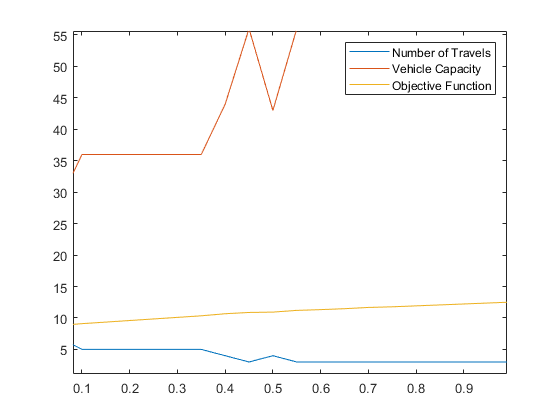

plot(value(cTau),value(nTravels),'DisplayName','Number of Travels')
hold on
plot(value(cTau),value(Capacities),'DisplayName',"Vehicle Capacity")
plot(value(cTau),value(objective),'DisplayName','Objective Function')
legend
hold off

As $c^{\tau }$ increases, the value of the objective function clearly increases as well, because of a higher "tax" to be paid. Moreover, as such fixed cost per trip increases, we notice that it's more convienent to reduce the number of trips and increase the capacity of the vehicle (being the cost per vehicles fixed), so that more customers can be served within the same trip. In addition, we notice that 

## Exercise 4.3)

#### *a)*

Modifica funzione obiettivo


$$\begin{array}{l}
\min_{x,\bar{V} ,q} \;\;\;\;\;c^V \bar{V} +S^{-1} \sum_{s\;\in \;S} \left.{\left(c\right.}^T {\left\|l_i -l_j \right\|}_2 x_{i\ldotp j}^s +c^{\tau \;} T^s \right)\\
\\
s\ldotp t\ldotp \;\;\;\\
\sum_{j=0}^N {x^s }_{i,j} \;=\sum_{k=0}^N {x^s }_{k,i} \;\;\;\;\;\;\;\forall i:0\le i\le N,\forall s\in S\\
\sum_{j=0}^N {x^s }_{i,j} =0\;\;\;\;\;\;\;\;\forall i:1\le i\le N,\forall s\in S\\
\sum_{j=0}^N {q^s }_{i,j} -\sum_{k=0}^N {q^s }_{k,i} ={d^s }_i \;\;\;\;\;\;\forall i:1\le i\le N,\;\forall s\in S\\
0\le q_{i,j}^s \le \bar{V} \;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N,\forall s\in S\\
q_{i,j}^s \le x_{i,j}^s M\;\;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
x_{i,j}^s \in \left\lbrace 0,1\right\rbrace \;\;\;\;\;\;\;\;\;\;\forall i,j:0\le i,j\le N\ldotp \forall s\in S\\
T^s \ge 0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\forall s\in S\\
\bar{V} \in \aleph \\

\end{array}$$


b)

clear;
load data_4.3.mat

%c_tau = 0.2;
[N,S] = size(demand_scen);
Capacity = intvar(1);
T = intvar(1,S,'full');
M=100;
x = binvar(N+1,N+1,S, 'full'); 
q = sdpvar(N+1,N+1,S, 'full'); 
distances = [N+1,N+1];

for i=1:N+1
    for j=1:N+1
        distances (i,j) = sqrt( ((locations(i,1)-locations(j,1))^2) + (((locations(i,2)-locations(j,2))^2) ));
    end
end

for s=1:S
Cons =  sum(x(:,:,s),2) == transpose(sum(x(:,:,s),1));
Cons = [Cons, sum(x(2:end,:,s),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end,s),1)) - sum(q(2:end,:,s),2) == demand_scen(:,s)];
Cons = [Cons, q(:,:,s) >= 0];
Cons = [Cons, q(:,:,s) <= Capacity];
Cons = [Cons, q(:,:,s) <= x(:,:,s) .* M];
Cons = [Cons, T(:,s) == sum(x(1,:,s),2)];
end
Cons = [Cons, Capacity >= 0];
Cons=[Cons, T>=0];


% Cons =  sum(x,2) == transpose(sum(x,1));
% Cons = [Cons, sum(x(2:end,:),2) == 1];
% Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
% Cons = [Cons, q >= 0];
% Cons = [Cons, q <= Capacity];
% Cons = [Cons, q <= x .* M];
% Cons = [Cons, T == sum(x(1,:),2)];

for i=1:S
    distances(:,:,i) = distances(:,:,1);
end

obj = vehicle_cost * Capacity +  mean(squeeze(sum(sum(distances .* x,1),2))' + fixed_tour_cost .* T);


ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);
Result = optimize(Cons, obj, ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 340 rows, 1021 columns and 954 nonzeros
Model fingerprint: 0xadf31f8d
Variable types: 100 continuous, 921 integer (910 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [9e-03, 3e-01]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 1e+01]
Presolve removed 132 rows and 840 columns
Presolve time: 0.01s
Presolved: 208 rows, 181 columns, 1406 nonzeros
Variable types: 90 continuous, 91 integer (90 binary)
Found heuristic solution: objective 11.2111599

Root relaxation: objective 4.516015e+00, 144 iterations, 0.00 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0    4.51602    0   37   11.21116    4.51602  

Test 2 for stochastic problem:

clear;
load data_4.3.mat

[N,S] = size(demand_scen);
Capacity = intvar(1);
T = intvar(1,S);
M=100;
x = binvar(N+1,N+1,S, 'full'); 
q = sdpvar(N+1,N+1,S, 'full'); 


for s=1:S      
Cons =  sum(x(:,:,s),2) == transpose(sum(x(:,:,s),1));
Cons = [Cons, sum(x(2:end,:,s),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end,s),1)) - sum(q(2:end,:,s),2) == demand_scen(:,s)];
Cons = [Cons, T(:,s) == sum(x(1,:,s),2)];

    for i=1:N+1
        for j=1:N+1
Cons = [Cons, q(i,j,s) >= 0];
Cons = [Cons, q(i,j,s) <= Capacity];
Cons = [Cons, q(i,j,s) <= x(i,j,s) .* M];
        end 
    end
end

obj = vehicle_cost * Capacity +  mean(fixed_tour_cost .* T);

ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);

Result = optimize(Cons, obj, ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 329 rows, 211 columns and 943 nonzeros
Model fingerprint: 0xeb264522
Variable types: 110 continuous, 101 integer (100 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+02]
  Objective range  [2e-02, 3e-01]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 1e+01]
Presolve time: 0.00s

Explored 0 nodes (0 simplex iterations) in 0.02 seconds
Thread count was 1 (of 4 available processors)

Solution count 0

Model is infeasible or unbounded
Best objective -, best bound -, gap -


c)

Solving the averager:

customer_demands = mean(demand_scen,2);
Capacity = intvar(1);
T = intvar(1);
M=100;
N=length(customer_demands);
x = binvar(N+1,N+1,'full'); 
q = sdpvar(N+1,N+1,'full'); % Vedi forum

Cons =  sum(x,2) == transpose(sum(x,1));
Cons = [Cons, sum(x(2:end,:),2) == 1];
Cons = [Cons, transpose(sum(q(:,2:end),1)) - sum(q(2:end,:),2) == customer_demands];
Cons = [Cons, q >= 0];
Cons = [Cons, q <= Capacity];
Cons = [Cons, q <= x .* M];
Cons = [Cons, T == sum(x(1,:),2)];

obj = vehicle_cost * Capacity +  fixed_tour_cost .* T;

%Same solution with both settings
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);
%ops = sdpsettings ( 'solver','gurobi', 'gurobi.MIPGap',0.2);

Result = optimize(Cons, obj, ops);


Adjusting the value of the objective function by taking into account extra trips to some customers. This is a consequence of some $d_i$ to be, in certain scenarios, higher than the capacity of the vehicle: 

[N,S] = size(demand_scen);
Demand = value(Capacity) - demand_scen;
%Demand(Demand>=0) = 0;
Demand

Demand =     4.7113   -2.9955   -0.9605   -1.6680    4.4651    9.8113   -3.6487   -0.3113   -1.3743    0.5260
    4.6063   -3.0452   -2.1153   -0.3449    4.4984    9.8817   -0.9820    0.2810   -1.1442    2.0295
    4.3047   -3.5017   -3.0316   -2.8669    4.6445    9.8093   -4.7258   -0.7518   -2.1991    1.9594
    3.3134   -4.1957   -1.7737   -0.6841    4.6896    9.5222   -3.5394   -1.5675   -2.2160   -0.4176
    3.7085   -2.9821   -3.0503   -3.1970    4.2932    9.8460   -1.3547    1.2768   -0.3788    1.6429
    3.2254   -4.3995   -1.9647   -0.5798    4.3708    9.9697   -1.1375   -0.2702   -0.8393    1.8947
    4.8130   -0.4617   -0.3887   -1.4613    3.0616    9.9888   -4.9742    0.8192   -0.9817    0.7017
    4.0806   -1.3300   -1.8309   -2.4335    3.9846    9.9212   -2.9077    1.1456   -0.8451    0.3898
    4.8014   -0.9808   -2.6513   -1.2443    3.4076    9.7179   -3.3042    1.5263   -1.2095    1.6328


NewT = 0;
for i=1:N
    for j=1:S
        if Demand(i,j)<0
            NewT=NewT+1+floor(abs(Demand(i,j))/Capacity);
        end
    end
end
value(NewT)

ans = 50

NewObj = value(obj) + 1/S*(NewT * fixed_tour_cost);
value(NewObj)

ans = 6.4000